Change the temperature here according to your heart's desire

% open the googP_logits.mat file from get_logits folder

introduce_functions;
temperature = 100;


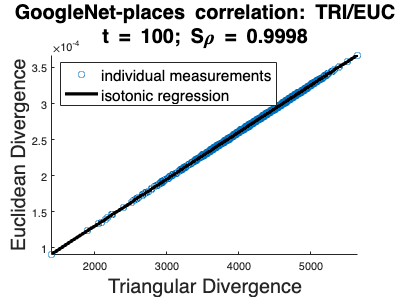

% Many to many

logits = googP_logits(1:10000,:);

smData = soft_max(logits,temperature);

perm=randperm(10000);

v1=perm (1:5000);
v2=perm(5001:end);

dists1 = TRI(smData(v1,:),smData(v2,:));
dists2 = EUC(logits(v1,:),logits(v2,:));

chart_title1 = strcat("GoogleNet-places"," correlation: TRI/EUC");
chart_title2 = strcat("t = ",num2str(temperature));
chart_title = [chart_title1,chart_title2];

shepard_spear(dists1,dists2,chart_title,"Triangular Divergence","Euclidean Divergence");

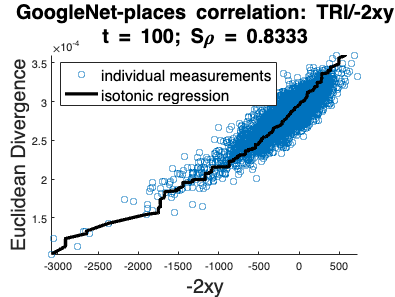

% 1 to many


TWOXY = @(X,Y) 2 * sum(X .* Y,2);

smData = soft_max(logits,temperature);

perm=randperm(10000);

v1=perm (1:5000);
v2=perm(5001:end);

dists1 = TRI(smData(v1,:),smData(v2,:));
dists2 = TWOXY(logits(v1,:),logits(v2,:));

chart_title1 = strcat("GoogleNet-places"," correlation: TRI/-2xy");
chart_title2 = strcat("t = ",num2str(temperature));
chart_title = [chart_title1,chart_title2];

shepard_spear(dists1,-dists2,chart_title,"-2xy","Euclidean Divergence");